This notebook is a collection of numerical analysis problems in wood and biomaterials engineering that have been solved in MATLAB, with the goal of showcasing how numerical algorithms can be applied in the fields of biomaterials, bioenergy, structures, and energy. These problems were inspired by my numerical analysis class and project I did there, where I recognized the importance of numerical methods in solving complex engineering problems.

From numerical differentiation and integration to solving errors, initial value problems (IVPs), linear multi-step methods, partial differential equations (PDEs), and systems of linear equations, these algorithms form the backbone of many engineering solutions. The code is designed to be clear and accessible, allowing others to learn how to implement these techniques effectively, especially in the context of biomaterials, energy, bioenergy engineering, and structural applications.

By understanding and applying these numerical algorithms, we can enhance the design, performance, and sustainability of materials and structures in engineering projects, particularly those related to renewable energy and bio-based materials.~ Niyel

## ***Numerical Differentiation***

*Estimating the Rate of Stress Increase in a Wooden Beam using Newton's Forward Formula*

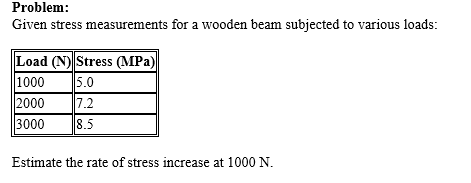

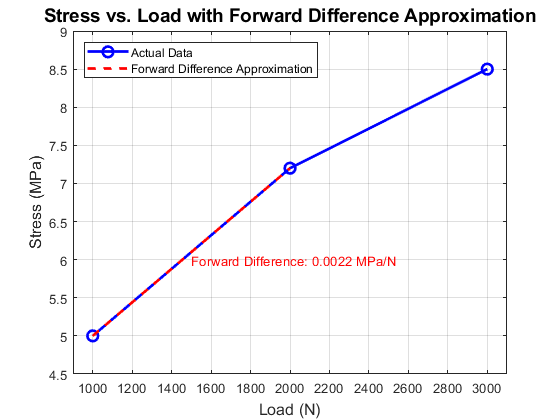

% Given Data
load_N = [1000, 2000, 3000]; % Load in Newtons
stress_MPa = [5.0, 7.2, 8.5]; % Stress in MPa

% Step Size
h = load_N(2) - load_N(1);

% Forward Difference Approximation
forward_difference = (stress_MPa(2) - stress_MPa(1)) / h;

% Create the plot
figure;
plot(load_N, stress_MPa, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

x_fd = [load_N(1), load_N(1) + h];
y_fd = [stress_MPa(1), stress_MPa(1) + forward_difference * h];
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);

xlabel('Load (N)', 'FontSize', 12);
ylabel('Stress (MPa)', 'FontSize', 12);
title('Stress vs. Load with Forward Difference Approximation', 'FontSize', 14);

legend('Actual Data', 'Forward Difference Approximation', 'Location', 'northwest');

text(1500, 6, sprintf('Forward Difference: %.4f MPa/N', forward_difference), ...
    'FontSize', 10, 'Color', 'r');
xlim([900, 3100]);
ylim([4.5, 9]);

grid on;

fprintf('Rate of Stress Increase at 1000 N: %.4f MPa/N\n', forward_difference);

Rate of Stress Increase at 1000 N: 0.0022 MPa/N


*Estimating the Rate of Moisture Loss at the End of a Drying Process using backward difference*

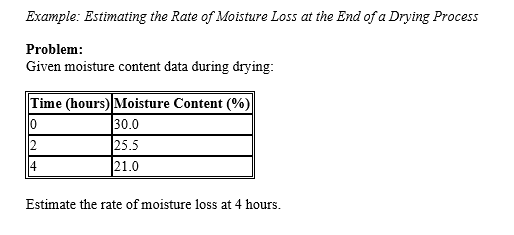


% Given data
time = [0, 2, 4];             % Time in hours
moisture_content = [30.0, 25.5, 21.0]; % Moisture content in %
clear length
% Calculate the backward difference
n = length(moisture_content);
delta_f = moisture_content(n) - moisture_content(n-1); % f(x_n) - f(x_(n-1))

% Calculate h (the time step)
h = time(n) - time(n-1); % Time difference (2 hours)

% Calculate the rate of moisture loss using backward difference
rate_moisture_loss = delta_f / h; % Moisture loss per hour (Backward difference)

% Display the result in the command window
fprintf('Rate of moisture loss: %.4f %% per hour\n', rate_moisture_loss);

Rate of moisture loss: -2.2500 % per hour


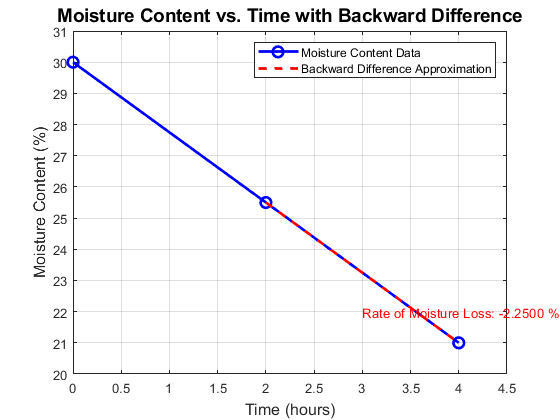


% Create the plot
figure;

% Plot moisture content vs time
plot(time, moisture_content, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

% Highlight the backward difference calculation on the plot
x_fd = [time(n-1), time(n)];
y_fd = [moisture_content(n-1), moisture_content(n)]; % Line connecting two data points
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);

% Add labels and title
xlabel('Time (hours)', 'FontSize', 12);
ylabel('Moisture Content (%)', 'FontSize', 12);
title('Moisture Content vs. Time with Backward Difference', 'FontSize', 14);

% Add legend
legend('Moisture Content Data', 'Backward Difference Approximation', 'Location', 'northeast');

% Add text annotation for the backward difference value
text(3, 22, sprintf('Rate of Moisture Loss: %.4f %%/hr', rate_moisture_loss), ...
    'FontSize', 10, 'Color', 'r');

% Adjust axis limits for better visibility
xlim([0, 4.5]);
ylim([20, 31]);

% Add grid
grid on;

*Calculating the Rate of Temperature Increase in a Bioenergy Reactor using forward difference*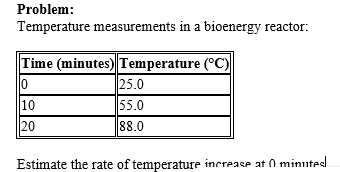

% Given data
time = [0, 10, 20];               % Time in minutes
temperature = [25.0, 55.0, 88.0]; % Temperature in °C

% Calculate the forward difference
delta_f = temperature(2) - temperature(1); % f(x_1) - f(x_0)

% Calculate h (the time step)
h = time(2) - time(1); % Time difference (10 minutes)

% Calculate the rate of temperature increase
rate_temp_increase = delta_f / h; % Rate of temperature increase (°C per minute)

% Display results
fprintf('Rate of Temperature Increase at 0 minutes: %.2f°C per minute\n', rate_temp_increase);

Rate of Temperature Increase at 0 minutes: 3.00°C per minute


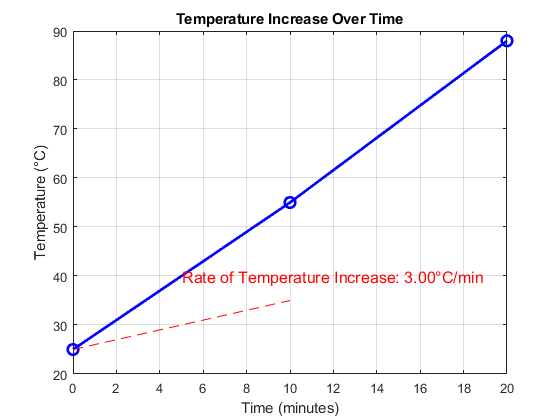


% Plotting the temperature increase over time
figure;

% Plot Temperature vs Time
plot(time, temperature, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Time (minutes)');
ylabel('Temperature (°C)');
title('Temperature Increase Over Time');
grid on;

% Annotate rate of increase
text(5, 40, sprintf('Rate of Temperature Increase: %.2f°C/min', rate_temp_increase), 'FontSize', 12, 'Color', 'r');


hold on;
plot([0, 10], [25, 35], 'r--');  % A line for the calculated rate over the interval
hold off;

*Estimating the Rate of Heat Transfer in a Wood Sample*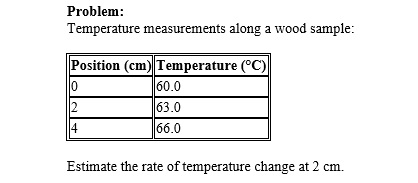

% Estimating the Rate of Stress Increase in a Wooden Beam

% Given Data
load_N = [1000, 2000, 3000]; % Load in Newtons
stress_MPa = [5.0, 7.2, 8.5]; % Stress in MPa

% Step Size
h = load_N(2) - load_N(1);

% Forward Difference Approximation
forward_difference = (stress_MPa(2) - stress_MPa(1)) / h;

% Create the plot
figure;
plot(load_N, stress_MPa, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

% Plot the forward difference approximation
x_fd = [load_N(1), load_N(1) + h];
y_fd = [stress_MPa(1), stress_MPa(1) + forward_difference * h];
plot(x_fd, y_fd, 'r--', 'LineWidth', 2);


xlabel('Load (N)', 'FontSize', 12);
ylabel('Stress (MPa)', 'FontSize', 12);
title('Stress vs. Load with Forward Difference Approximation', 'FontSize', 14);
legend('Actual Data', 'Forward Difference Approximation', 'Location', 'northwest');
text(1500, 6, sprintf('Forward Difference: %.4f MPa/N', forward_difference), ...
    'FontSize', 10, 'Color', 'r');


xlim([900, 3100]);
ylim([4.5, 9]);

% Add grid
grid on;



fprintf('Rate of Stress Increase at 1000 N: %.4f MPa/N\n', forward_difference);

Rate of Stress Increase at 1000 N: 0.0022 MPa/N


*Calculating the Rate of Shrinkage in a Wood Panel*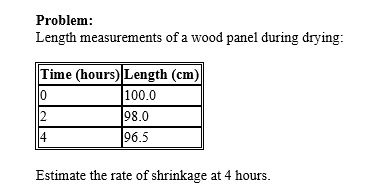

% Given data
time = [0, 2, 4];                % Time in hours
length = [100.0, 98.0, 96.5];    % Length in cm

% Calculate the backward difference
n = length(3);       % Length at 4 hours
n_minus_1 = length(2);  % Length at 2 hours
delta_length = n - n_minus_1; % f(x_n) - f(x_(n-1))

% Calculate h (the time step)
h = time(3) - time(2); % Time difference (2 hours)

% Calculate the rate of shrinkage
rate_shrinkage = delta_length / h; % Rate of shrinkage (cm per hour)

% Display results
fprintf('Rate of Shrinkage at 4 hours: %.2f cm per hour\n', rate_shrinkage);

Rate of Shrinkage at 4 hours: -0.75 cm per hour


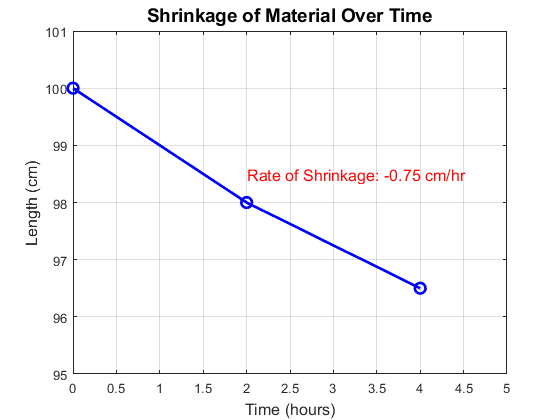


% Visualization: Plot Length vs Time
figure;
plot(time, length, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Time (hours)', 'FontSize', 12);
ylabel('Length (cm)', 'FontSize', 12);
title('Shrinkage of Material Over Time', 'FontSize', 14);
grid on;

text(2, 98.5, sprintf('Rate of Shrinkage: %.2f cm/hr', rate_shrinkage), 'FontSize', 12, 'Color', 'r');

% Display the plot
xlim([0, 5]);
ylim([95, 101]);

## Numerical Integration

**Calculating the Total Stress on a Wooden Beam**

**Problem:**Given a beam with a varying stress distributionf(x) = 2x + 1 over the interval [0,10], estimate the total stress using the Trapezoidal Rule with n=4 intervals.

% Define the function to be integrated
f = @(x) 2 * x + 1;  % Function representing the total stress on a wooden beam

% Define the interval [a, b] and number of intervals n
a = 0;   % Lower bound
b = 10;  % Upper bound
n = 4;   % Number of intervals

% Calculate step size
h = (b - a) / n;

% Initialize the result
trapezoidal_result = f(a) + f(b);

% Compute the intermediate terms
for i = 1:n-1
    x_i = a + i * h;
    trapezoidal_result = trapezoidal_result + 2 * f(x_i);
end

% Finalize the trapezoidal rule calculation
trapezoidal_result = (h / 2) * trapezoidal_result;

% Display the result
fprintf('total stress: %.4f\n', trapezoidal_result);

total stress: 110.0000


**Estimating the Energy Output in a Bioenergy Reactor**

**Problem:**Given the energy output function $f(x) = x^2$ over the interval [1,5], estimate the total energy using Simpson’s One-Third Rule with n = 4 intervals.

% Simpson's One-Third Rule Integration

% Define the function to integrate
f = @(x) x.^2;  % The function is f(x) = x^2

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 5;    % Upper limit of integration
n = 4;    % Number of sub-intervals (must be even for Simpson's rule)

% Calculate the step size (h)
h = (b - a) / n;    % Step size

% Evaluate the function at equally spaced points
x = linspace(a, b, n+1);  % Create array of points from a to b
fx = f(x);    % Evaluate the function at those points

% Apply Simpson's One-Third Rule formula
I_simp = (h/3) * (fx(1) + 4*sum(fx(2:2:end-1)) + 2*sum(fx(3:2:end-2)) + fx(end));

% Display the result of integration
disp(['Energy Output: ', num2str(I_simp)]);

Energy Output: 41.3333


**Calculating the Volume of a Wooden Cylinder**

**Problem:**Given the volume function $f(x) = \pi x^2$ over the interval [2,5], estimate the total volume using Simpson’s Three-Eighth Rule with n=3 intervals.

% Simpson's Three-Eighth Rule Integration

% Define the function to integrate
f = @(x) pi*x.^2;  % The function is f(x) = pi*x^2

% Define the integration limits and number of intervals
a = 2;    % Lower limit of integration
b = 5;    % Upper limit of integration
n = 3;    % Number of sub-intervals (must be a multiple of 3)

% Calculate the step size (h)
h = (b - a) / n;    % Step size

% Evaluate the function at equally spaced points
x = linspace(a, b, n+1);  % Create array of points from a to b
fx = f(x);    % Evaluate the function at those points

% Apply Simpson's Three-Eighth Rule formula
I_simp38 = (3*h/8) * (fx(1) + 3*sum(fx(2:3:end-1)) + 3*sum(fx(3:3:end-2)) + 2*sum(fx(4:3:end-3)) + fx(end));

% Display the result of integration
disp(['Volume of Wooden Cylinder: ', num2str(I_simp38)]);

Volume of Wooden Cylinder: 65.9734


**Estimating the Wood Volume in a Log**

Problem: Given the volume function f(x)= xover the interval [1,4], estimate the total volume using Boole’s Rule with n=4 intervals.


% Boole's Rule Integration

% Define the function to integrate
f = @(x) x;  % The volume function f(x) = x

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 4;    % Upper limit of integration
n = 4;    % Number of sub-intervals (must be a multiple of 4 for Boole's Rule)

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Boole's Rule
I_boole = (7 * h / 90) * (7 * fx(1) + 32 * (fx(2) + fx(4)) + 12 * fx(3) + 7 * fx(5));

% Display the result of integration
disp(['Estimated Volume using Boole''s Rule: ', num2str(I_boole)]);

Estimated Volume using Boole's Rule: 13.125


**Calculating the Heat Transfer in a Biomaterial**

**Problem:** Given the heat transfer function $f(x) = x^3$ over the interval [0,3], estimate the total heat transfer using Weddle’s Rule with n=6 intervals

% Weddle's Rule Integration

% Define the heat transfer function to integrate
f = @(x) x.^3;  % The heat transfer function f(x) = x^3

% Define the integration limits and number of intervals
a = 0;    % Lower limit of integration
b = 3;    % Upper limit of integration
n = 6;    % Number of sub-intervals (must be a multiple of 6 for Weddle's Rule)

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Weddle's Rule
I_weddle = (3 * h / 10) * (fx(1) + 5 * (fx(2) + fx(4) + fx(6)) + 2 * (fx(3) + fx(5)) + 5 * fx(7));

% Display the result of integration
disp(['Estimated Heat Transfer using Weddle''s Rule: ', num2str(I_weddle)]);

Estimated Heat Transfer using Weddle's Rule: 37.2937


## **Errors in Numerical Methods**

**Trapezoidal Rule Error**

Estimate the error in the Trapezoidal Rule for the function$f\left(x\right)=x^2 $  over [1,4]with n=4 intervals, applied to estimate the stress distribution in a wooden beam

% Trapezoidal Rule Error Estimation

% Define the function
f = @(x) x.^2;  % The function f(x) = x^2

% Define the integration limits and number of intervals
a = 1;    % Lower limit of integration
b = 4;    % Upper limit of integration
n = 4;    % Number of sub-intervals

% Compute exact integral
exact_integral = (b^3 / 3) - (a^3 / 3);  % Exact value of the integral

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying the Trapezoidal Rule
I_T = (h / 2) * (fx(1) + 2 * sum(fx(2:end-1)) + fx(end));

% Compute error estimate
f_double_prime = 2;  % Second derivative of f(x) = x^2
error_estimate = -((b - a) / (12 * n^2)) * f_double_prime;

% Display results
disp(['Exact Integral: ', num2str(exact_integral)]);

Exact Integral: 21


disp(['Estimated Integral using Trapezoidal Rule: ', num2str(I_T)]);

Estimated Integral using Trapezoidal Rule: 21.2812


disp(['Error Estimate: ', num2str(error_estimate)]);

Error Estimate: -0.03125


**Simpson’s One-Third Rule Error**

Estimate the error in Simpson’s One-Third Rule for the function $f\left(x\right)=e^{x\;}$ over [0,2] with n=4 intervals, applied to estimate the energy output of a bioenergy system.

% Simpson's One-Third Rule Error Estimation

% Define the function
f = @(x) exp(x);  % The function f(x) = e^x

% Define the integration limits and number of intervals
a = 0;    % Lower limit of integration
b = 2;    % Upper limit of integration
n = 4;    % Number of sub-intervals

% Compute exact integral
exact_integral = exp(b) - exp(a);  % Exact value of the integral

% Step size calculation
h = (b - a) / n;    % Step size

% Evaluate the function at specified points
x = a:h:b;  % Create an array of points from a to b
fx = f(x);  % Evaluate the function at those points

% Applying Simpson's One-Third Rule
I_S = (h / 3) * (fx(1) + 4 * sum(fx(2:2:end)) + 2 * sum(fx(3:2:end)) + fx(end));

% Compute error estimate
f_fourth_derivative = exp(x);  % Fourth derivative of f(x) = e^x
error_estimate = -((b - a)^5 / (180 * n^4)) * max(f_fourth_derivative);

% Display results
disp(['Exact Integral: ', num2str(exact_integral)]);

Exact Integral: 6.3891


disp(['Estimated Integral using Simpson’s One-Third Rule: ', num2str(I_S)]);

Estimated Integral using Simpson’s One-Third Rule: 8.8542


disp(['Error Estimate: ', num2str(error_estimate)]);

Error Estimate: -0.0051313


## **Initial Value Problems (I.V.P)**

**Lipschitz Condition**

Determine if the moisture diffusion rate function $f(M) = \sqrt{M}$ where **M** is the moisture content in wood) satisfies the Lipschitz condition over the interval **[10,50]** with a proposed Lipschitz constant L=0.5

The **Lipschitz condition** ensures that the rate of moisture diffusion is bounded, preventing overly rapid changes in moisture content

% Lipschitz Condition Verification in Moisture Diffusion (Wood Biomaterials)

% Define the moisture diffusion function
f = @(M) sqrt(M);  % Moisture diffusion rate function

% Define the interval for moisture content (M)
M_min = 10;  % Minimum moisture content
M_max = 50;  % Maximum moisture content
L = 0.5;     % Proposed Lipschitz constant

% Generate test points
n = 200;  % Number of test points for analysis
M = linspace(M_min, M_max, n);  % Generate M values in [M_min, M_max]
[M1, M2] = meshgrid(M, M);      % Create grid for (M1, M2) pairs

% Compute the difference quotient
diff_quotient = abs(f(M2) - f(M1)) ./ abs(M2 - M1);
diff_quotient(M1 == M2) = 0;  % Avoid division by zero for M1 = M2

% Check if Lipschitz condition is satisfied
is_lipschitz = all(diff_quotient(:) <= L);  % Verify all values against L

% Display results
if is_lipschitz
    disp(['The function satisfies the Lipschitz condition with L = ', num2str(L)]);
else
    disp(['The function does NOT satisfy the Lipschitz condition with L = ', num2str(L)]);
end

The function satisfies the Lipschitz condition with L = 0.5


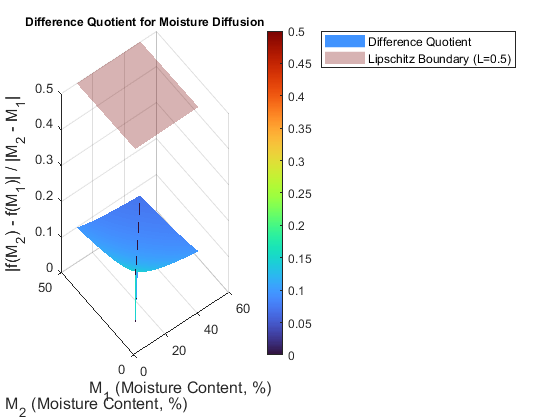


% Visualization
figure;
surf(M1, M2, diff_quotient, 'EdgeColor', 'none');
colormap turbo;
colorbar;
xlabel('M_1 (Moisture Content, %)', 'FontSize', 12);
ylabel('M_2 (Moisture Content, %)', 'FontSize', 12);
zlabel('|f(M_2) - f(M_1)| / |M_2 - M_1|', 'FontSize', 12);
title('Difference Quotient for Moisture Diffusion', 'FontSize', 9);

% Add Lipschitz boundary plane
hold on;
plane_z = L * ones(size(M1));
surf(M1, M2, plane_z, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
legend('Difference Quotient', 'Lipschitz Boundary (L=0.5)');

**Picard Iteration Scheme in Biomaterials Engineering**

Problem:

Determine the temperature distribution in a bio-composite material during heat conduction using the Picard Iteration scheme.

The heat conduction in a material can be modeled by the equation:$,T_{n+1} = \frac{1}{k}(q - h T_n)$

where:

- $T_n$�: Temperature at the n-th iteration.

- q: Heat source term $q = 500 \, \text{W/m}^2$

- h: Heat transfer coefficient $h = 20 \, \text{W/m}^2.$

- k: Thermal conductivity$ k = 0.5 \, \text{W/mK}$

% Picard Iteration Scheme for Heat Conduction in Biomaterials

% Given parameters
q = 500;      % Heat source term (W/m^2)
h = 200;       % Heat transfer coefficient (W/m^2)
k = 0.5;      % Thermal conductivity (W/mK)
tol = 1e-4;   % Convergence tolerance
max_iter = 100; % Maximum number of iterations

% Initial guess for temperature
T_prev = 0;  % Initial temperature guess (arbitrary)
T_curr = 0;  % Initialize current temperature
error = inf; % Initialize error
iter = 0;    % Iteration counter

% Picard Iteration Loop
while error > tol && iter < max_iter
    T_curr = (1/k) * (q - h * T_prev); % Picard Iteration formula
    error = abs(T_curr - T_prev);      % Compute error
    T_prev = T_curr;                   % Update for next iteration
    iter = iter + 1;                   % Increment iteration counter
end

% Display results
if error <= tol
    fprintf('Converged solution: T = %.4f K\n', T_curr);
    fprintf('Number of iterations: %d\n', iter);
else
    fprintf('Solution did not converge within %d iterations.\n', max_iter);
end

Solution did not converge within 100 iterations.


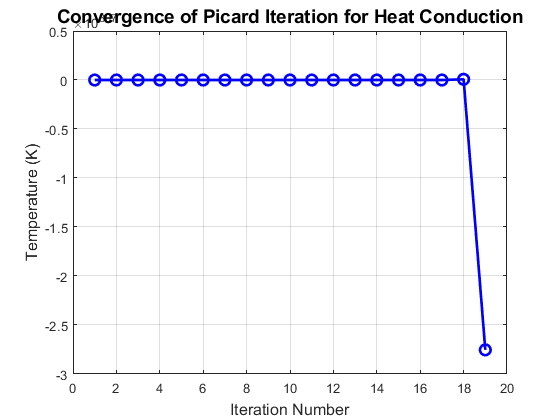


% Plot convergence
T_values = zeros(1, iter);  % To store temperature values for plotting
T_values(1) = T_curr;       % Store first temperature
for i = 2:iter
    T_values(i) = (1/k) * (q - h * T_values(i-1));
end

figure;
plot(1:iter, T_values, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Iteration Number', 'FontSize', 12);
ylabel('Temperature (K)', 'FontSize', 12);
title('Convergence of Picard Iteration for Heat Conduction', 'FontSize', 14);
grid on;

**Solving a Biomaterials Cooling Problem Using Euler and Modified Euler Methods**

**Problem :**A biomaterial is cooling from an initial temperature $ T_0 = 100^\circ C $in a controlled environment with ambient temperature $T_a = 25^\circ C.$ The rate of cooling is governed by Newton's law of cooling:


$$\frac{dT}{dt} = -k (T - T_a)$$


where $k = 0.1 \, \text{min}^{-1} $is the cooling constant. Estimate the temperature of the biomaterial after 10 minutes using:

- Euler's Method.

- Modified Euler's Method.

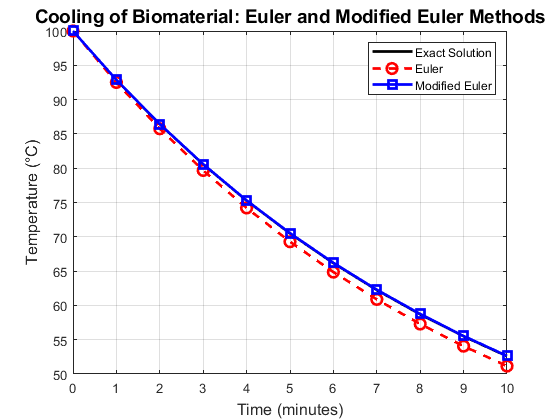

% Euler and Modified Euler Methods for Biomaterial Cooling Problem

% Given Parameters
k = 0.1;            % Cooling constant (min^-1)
T_a = 25;           % Ambient temperature (deg C)
T_0 = 100;          % Initial temperature (deg C)
t_end = 10;         % Time duration (minutes)
h = 1;              % Step size (minutes)

% Define the derivative function
dTdt = @(T) -k * (T - T_a);

% Initialize time and temperature arrays
n_steps = t_end / h;  % Number of steps
time = 0:h:t_end;     % Time points
T_euler = zeros(1, n_steps + 1);
T_mod_euler = zeros(1, n_steps + 1);

% Set initial conditions
T_euler(1) = T_0;
T_mod_euler(1) = T_0;

% Euler's Method
for i = 1:n_steps
    T_euler(i + 1) = T_euler(i) + h * dTdt(T_euler(i));
end

% Modified Euler's Method
for i = 1:n_steps
    T_predict = T_mod_euler(i) + h * dTdt(T_mod_euler(i));  % Predict
    T_mod_euler(i + 1) = T_mod_euler(i) + (h / 2) * ...
        (dTdt(T_mod_euler(i)) + dTdt(T_predict));          % Correct
end

% Analytical Solution for Comparison
T_exact = T_a + (T_0 - T_a) * exp(-k * time);

% Plot Results
figure;
plot(time, T_exact, 'k-', 'LineWidth', 2, 'DisplayName', 'Exact Solution');
hold on;
plot(time, T_euler, 'ro--', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Euler');
plot(time, T_mod_euler, 'bs-', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Modified Euler');
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Cooling of Biomaterial: Euler and Modified Euler Methods', 'FontSize', 14);
legend('Location', 'northeast');
grid on;


% Display Final Results
fprintf('Final Temperature at t = %.1f minutes:\n', t_end);

Final Temperature at t = 10.0 minutes:


fprintf('Euler Method: %.2f °C\n', T_euler(end));

Euler Method: 51.15 °C


fprintf('Modified Euler Method: %.2f °C\n', T_mod_euler(end));

Modified Euler Method: 52.64 °C


fprintf('Exact Solution: %.2f °C\n', T_exact(end));

Exact Solution: 52.59 °C


**Solving Biomass Processing Heat Transfer Problem Using Runge-Kutta Methods**

**Problem**:In the biomass processing system, heat transfer is critical in determining the efficiency of the process. Consider a biomass reactor where the temperature T of biomass is governed by the differential equation:


$$\frac{dT}{dt} = -k (T - T_a)$$


where:

- $k = 0.1 \, \text{min}^{-1}$ is the heat transfer coefficient,

- $T_a = 25^\circ C$is the ambient temperature,

- $T_0 = 100^\circ C$ is the initial temperature of biomass at t=0

- T(t) is the temperature at time t

**Second Order Methods**

% Biomass Processing Heat Transfer Problem - Runge-Kutta 2nd Order Method

% Given Parameters
k = 0.1;          % Heat transfer coefficient (min^-1)
T_a = 25;         % Ambient temperature (deg C)
T_0 = 100;        % Initial temperature (deg C)
t_end = 10;       % Time duration (minutes)
h = 1;            % Step size (minutes)
C_p = 2.5;        % Specific heat capacity (J/g°C)
mass = 500;       % Mass of biomass (g)

% Define the derivative function
dTdt = @(T) -k * (T - T_a);

% Initialize time and temperature arrays
n_steps = t_end / h;  % Number of steps
time = 0:h:t_end;     % Time points
T_RK2 = zeros(1, n_steps + 1);

% Set initial conditions
T_RK2(1) = T_0;

% Runge-Kutta 2nd Order Method (RK2)
for i = 1:n_steps
    k1 = dTdt(T_RK2(i));
    k2 = dTdt(T_RK2(i) + h * k1);
    T_RK2(i + 1) = T_RK2(i) + (h / 2) * (k1 + k2);
end

% Energy Yield (Joules)
energy_yield_RK2 = mass * C_p * (T_RK2 - T_a);  % Energy in Joules

% Display results
disp('Biomass Cooling using RK2 - Temperature and Energy Yield:');

Biomass Cooling using RK2 - Temperature and Energy Yield:


disp([time', T_RK2', energy_yield_RK2']);

   1.0e+04 *
         0    0.0100    9.3750
    0.0001    0.0093    8.4844
    0.0002    0.0086    7.6784
    0.0003    0.0081    6.9489
    0.0004    0.0075    6.2888
    0.0005    0.0071    5.6913
    0.0006    0.0066    5.1507
    0.0007    0.0062    4.6613
    0.0008    0.0059    4.2185
    0.0009    0.0056    3.8178
    0.0010    0.0053    3.4551


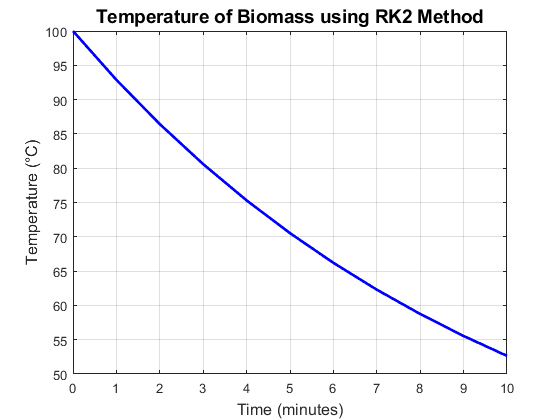


% Plot Temperature vs Time
figure;
plot(time, T_RK2, 'b-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Temperature of Biomass using RK2 Method', 'FontSize', 14);
grid on;

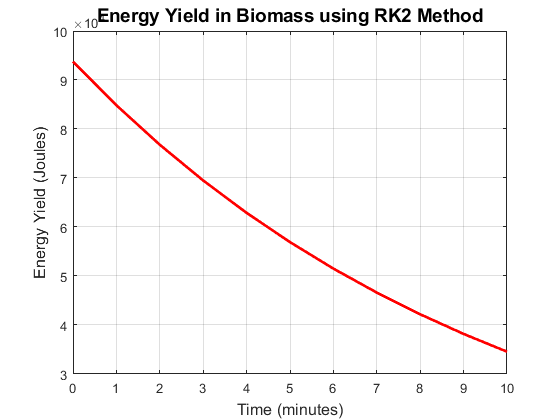


% Plot Energy Yield vs Time
figure;
plot(time, energy_yield_RK2, 'r-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Energy Yield (Joules)', 'FontSize', 12);
title('Energy Yield in Biomass using RK2 Method', 'FontSize', 14);
grid on;

**Third-Order Method**

% Biomass Processing Heat Transfer Problem - Runge-Kutta 3rd Order Method

% Runge-Kutta 3rd Order Method (RK3)
T_RK3 = zeros(1, n_steps + 1);
T_RK3(1) = T_0;

for i = 1:n_steps
    k1 = dTdt(T_RK3(i));
    k2 = dTdt(T_RK3(i) + (h / 2) * k1);
    k3 = dTdt(T_RK3(i) - h * k1 + 2 * h * k2);
    T_RK3(i + 1) = T_RK3(i) + (h / 6) * (k1 + 4 * k2 + k3);
end

% Energy Yield (Joules)
energy_yield_RK3 = mass * C_p * (T_RK3 - T_a);  % Energy in Joules

% Display results
disp('Biomass Cooling using RK3 - Temperature and Energy Yield:');

Biomass Cooling using RK3 - Temperature and Energy Yield:


disp([time', T_RK3', energy_yield_RK3']);

   1.0e+04 *
         0    0.0100    9.3750
    0.0001    0.0093    8.4828
    0.0002    0.0086    7.6755
    0.0003    0.0081    6.9451
    0.0004    0.0075    6.2841
    0.0005    0.0070    5.6861
    0.0006    0.0066    5.1450
    0.0007    0.0062    4.6553
    0.0008    0.0059    4.2123
    0.0009    0.0055    3.8114
    0.0010    0.0053    3.4487


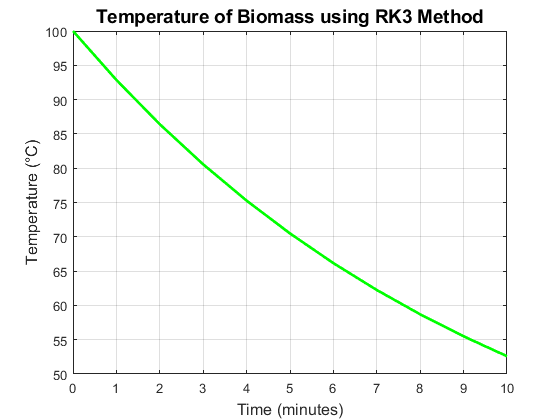


% Plot Temperature vs Time
figure;
plot(time, T_RK3, 'g-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Temperature of Biomass using RK3 Method', 'FontSize', 14);
grid on;

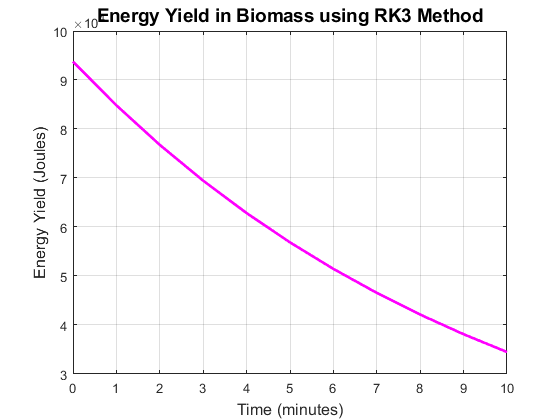


% Plot Energy Yield vs Time
figure;
plot(time, energy_yield_RK3, 'm-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Energy Yield (Joules)', 'FontSize', 12);
title('Energy Yield in Biomass using RK3 Method', 'FontSize', 14);
grid on;

4-th Order Method

% Biomass Processing Heat Transfer Problem - Runge-Kutta 4th Order Method

% Runge-Kutta 4th Order Method (RK4)
T_RK4 = zeros(1, n_steps + 1);
T_RK4(1) = T_0;

for i = 1:n_steps
    k1 = dTdt(T_RK4(i));
    k2 = dTdt(T_RK4(i) + (h / 2) * k1);
    k3 = dTdt(T_RK4(i) + (h / 2) * k2);
    k4 = dTdt(T_RK4(i) + h * k3);
    T_RK4(i + 1) = T_RK4(i) + (h / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
end

% Energy Yield (Joules)
energy_yield_RK4 = mass * C_p * (T_RK4 - T_a);  % Energy in Joules

% Display results
disp('Biomass Cooling using RK4 - Temperature and Energy Yield:');

Biomass Cooling using RK4 - Temperature and Energy Yield:


disp([time', T_RK4', energy_yield_RK4']);

   1.0e+04 *
         0    0.0100    9.3750
    0.0001    0.0093    8.4829
    0.0002    0.0086    7.6756
    0.0003    0.0081    6.9452
    0.0004    0.0075    6.2843
    0.0005    0.0070    5.6862
    0.0006    0.0066    5.1451
    0.0007    0.0062    4.6555
    0.0008    0.0059    4.2125
    0.0009    0.0055    3.8116
    0.0010    0.0053    3.4489


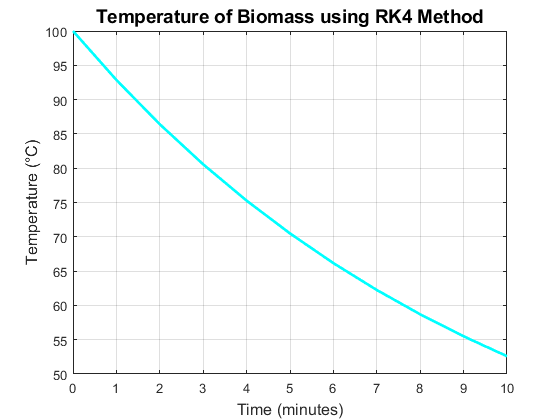


% Plot Temperature vs Time
figure;
plot(time, T_RK4, 'c-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Temperature of Biomass using RK4 Method', 'FontSize', 14);
grid on;

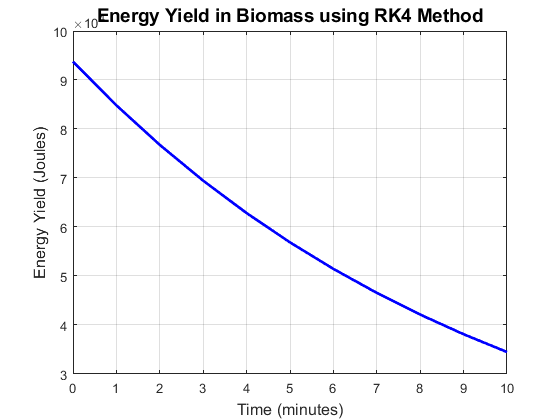


% Plot Energy Yield vs Time
figure;
plot(time, energy_yield_RK4, 'b-', 'LineWidth', 2);
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Energy Yield (Joules)', 'FontSize', 12);
title('Energy Yield in Biomass using RK4 Method', 'FontSize', 14);
grid on;

Exact Solution

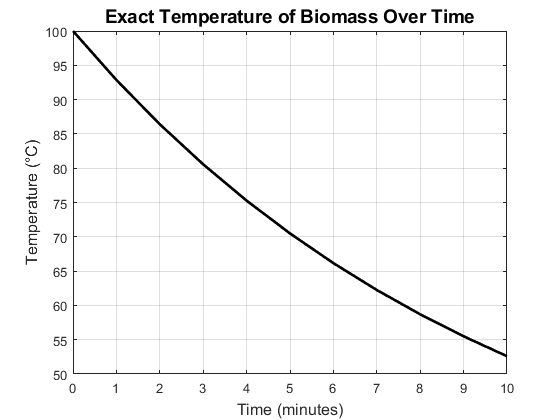

% Exact Solution for Temperature as a function of time
T_exact = T_a + (T_0 - T_a) * exp(-k * time);

% Plot Exact Solution vs Time
figure;
plot(time, T_exact, 'k-', 'LineWidth', 2, 'DisplayName', 'Exact Solution');
xlabel('Time (minutes)', 'FontSize', 12);
ylabel('Temperature (°C)', 'FontSize', 12);
title('Exact Temperature of Biomass Over Time', 'FontSize', 14);
grid on;


% Display the exact solution's final value
fprintf('Exact Temperature at t = %.1f minutes: %.2f °C\n', t_end, T_exact(end));

Exact Temperature at t = 10.0 minutes: 52.59 °C


## Linear Multi-Step Methods

**Stress-Strain Analysis**

Consider a wood beam subjected to an external load. The bending of the beam can be modeled using an ODE that describes the beam's deflection under load:  $\frac{d^2y}{dx^2}=\frac{M(x)}{EI}$

                              �where:

    M(x)  is the bending moment,

    E  is the modulus of elasticity,

    I  is the moment of inertia.

% Parameters
M0 = 10;               % Maximum moment (N*m)
E = 200e9;             % Modulus of elasticity (Pa)
I = 1e-6;              % Moment of inertia (m^4)
k = 1;                 % Constant for the bending moment function
h = 0.1;               % Step size
x_end = 1;             % End of the beam length
n_steps = x_end / h;  % Number of steps

% Initialize arrays
x = 0:h:x_end;         % x values
v = zeros(1, n_steps + 1); % Initialize v values (dy/dx)
y = zeros(1, n_steps + 1); % Initialize y values (deflection)

% Initial conditions
v(1) = 0;              % v(0) = 0
y(1) = 0;              % y(0) = 0

% Compute v_1 using Euler's method
dv_dx_0 = (M0 * sin(k * x(1))) / (E * I); % Calculate dv/dx at x=0
v(2) = v(1) + h * dv_dx_0; % v_1

% Compute y_1 using Euler's method
y(2) = y(1) + h * v(1);   % y_1

% Compute v_2 using Euler's method
dv_dx_1 = (M0 * sin(k * x(2))) / (E * I); % Calculate dv/dx at x=h
v(3) = v(2) + h * dv_dx_1; % v_2

% Compute y_2 using Euler's method
y(3) = y(2) + h * v(2);  % y_2

% 2-Step Adams-Bashforth Method
for n = 3:n_steps
    % Calculate f_n and f_(n-1)
    f_n = (M0 * sin(k * x(n))) / (E * I); % f_n = dv/dx at x_n
    f_n_1 = (M0 * sin(k * x(n-1))) / (E * I); % f_(n-1) = dv/dx at x_(n-1)
    
    % Compute v_n+1 using Adams-Bashforth formula
    v(n + 1) = v(n) + (h / 2) * (3 * f_n - f_n_1); % v_(n+1)
    
    % Compute y_n+1 using the latest v value
    y(n + 1) = y(n) + h * v(n); % y_(n+1)
end

% Display results
disp('x values:');

x values:


disp(x);

  Columns 1 through 7
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000
  Columns 8 through 11
    0.7000    0.8000    0.9000    1.0000


disp('v values (dy/dx):');

v values (dy/dx):


disp(v);

   1.0e-04 *
  Columns 1 through 7
         0         0    0.0050    0.0174    0.0346    0.0564    0.0826
  Columns 8 through 11
    0.1130    0.1472    0.1849    0.2257


disp('y values (deflection):');

y values (deflection):


disp(y);

   1.0e-05 *
  Columns 1 through 7
         0         0         0    0.0050    0.0224    0.0570    0.1134
  Columns 8 through 11
    0.1960    0.3090    0.4562    0.6411


**Simulating Biomass Degradation using 3rd Order Adams-Moulton Method**

Problem : Consider a biomass degradation model, where the rate of degradation is modeled by the differential equation:$\frac{dB}{dt} = -kB^ndt$

Where:

- B(t) is the biomass at time t,

- k is the degradation rate constant,

- n is the order of the degradation process (for example, n=1 corresponds to first-order degradation).

% Parameters for the biomass degradation model
k = 0.05;  % Degradation rate constant
n = 1;     % Order of the degradation process
B_0 = 100; % Initial biomass (in kg)
t_end = 20; % Time period (in hours)
h = 2;     % Time step (in hours)
n_steps = t_end / h; % Number of time steps

% Initial conditions
time = 0:h:t_end;
B = zeros(1, n_steps + 1);
B(1) = B_0;

% Define the biomass degradation function
f = @(B) -k * B^n;

% Apply the 3rd-order Adams-Moulton method
for n = 3:n_steps
    % Use Euler's method for the first two steps
    if n == 2
        B(2) = B(1) + h * f(B(1));
    elseif n == 3
        B(3) = B(2) + h * f(B(2));
    else
        % 3rd-order Adams-Moulton method
        B(n + 1) = B(n) + (h / 24) * (9 * f(B(n)) + 19 * f(B(n-1)) - 5 * f(B(n-2)));
    end
end

% Display the results
disp('Time (hours)    Biomass (kg)');

Time (hours)    Biomass (kg)


disp([time', B']);

     0   100
     2     0
     4     0
     6     0
     8     0
    10     0
    12     0
    14     0
    16     0
    18     0
    20     0


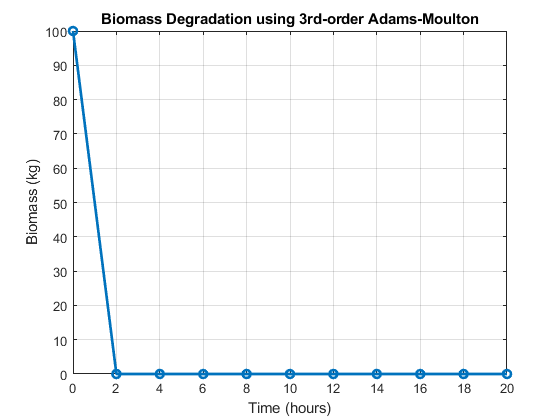


% Plot the results
figure;
plot(time, B, '-o', 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Biomass (kg)');
title('Biomass Degradation using 3rd-order Adams-Moulton');
grid on;

## Numerical Solutions of Partial Differential Equations

Simulating heat diffusion using Finite Difference Approximation

Problem:Simulate the heat diffusion in a wooden log of length L=1 meter using the heat equation: $\frac{\partial u}{\partial t}=\alpha\frac{\partial^2u}{\partial x^2}$

- Thermal diffusivity of wood,${\alpha=0.01m^2}{s}$

- Initial temperature distribution:$u\left(x,0\right)=\sin{\left(\pi x\right)}$            

- Boundary conditions: $u\left(0.t\right)=u\left(1,t\right)=0$           (fixed temperature at the ends)

- Time interval: $0\le t\le0.5\ $           seconds

- Number of spatial points:  N=10          

- Number of time steps:     M=50       

We are using the finite difference formula:$u_i^{n+1}=u_i^n+\alpha\frac{k}{h^2}\left(u_{i+1}^n-2u_i^n+u_{i-1}^n\right)$

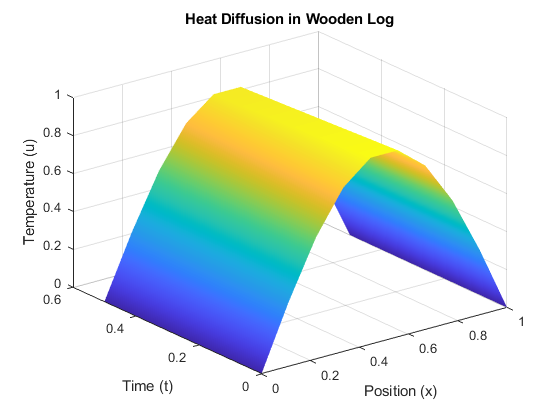

% Parameters
L = 1;                % Length of the wooden log
alpha = 0.01;         % Thermal diffusivity
T = 0.5;              % Total simulation time
N = 10;               % Number of spatial points
M = 50;               % Number of time steps

% Discretization
h = L / (N-1);        % Spatial step size
k = T / M;            % Time step size
lambda = alpha * k / h^2;

% Check stability condition
if lambda > 0.5
    error('Stability condition violated: lambda must be <= 0.5');
end

% Spatial grid
x = linspace(0, L, N);

% Initial condition: u(x,0) = sin(pi * x)
u = sin(pi * x);

% Store the solution at each time step
U = zeros(N, M+1);
U(:,1) = u;           % Initial temperature distribution

% Time-stepping using explicit finite difference method
for n = 1:M
    % Create a copy of the current time step for updates
    u_new = u;
    
    % Update the temperature at interior points
    for i = 2:N-1
        u_new(i) = u(i) + lambda * (u(i+1) - 2*u(i) + u(i-1));
    end
    
    % Apply boundary conditions: u(0,t) = u(1,t) = 0
    u_new(1) = 0;
    u_new(N) = 0;
    
    % Store the updated temperature distribution
    U(:, n+1) = u_new;
    
    % Move to the next time step
    u = u_new;
end

% Create a meshgrid for plotting
t = linspace(0, T, M+1);
[X, T_grid] = meshgrid(x, t);

% Transpose U to match the dimensions of the meshgrid for surf
U = U';

% Plot the temperature distribution over time
figure;
surf(X, T_grid, U);
shading interp;
xlabel('Position (x)');
ylabel('Time (t)');
zlabel('Temperature (u)');
title('Heat Diffusion in Wooden Log');

Simulating Temperature Distribution in a Wooden Plate using Finite Difference Method for Laplace Equation

Problem:Find the steady-state temperature distribution in a square wooden plate of dimensions                               meters with: $\frac{\partial^2u}{\partial x^2}+\frac{\partial^2u}{\partial y^2}=0$

- Boundary conditions:   $u=100^\circ c$ on the left edge,  $$u=0^\circ c\ $$on the other edges.

- Assume natural wood properties.

% Parameters
L = 1;                    % Length of the plate (1 meter)
N = 10;                   % Number of interior grid points (N x N grid)
dx = L / (N + 1);          % Spatial step size (0.1 meters)

% Initialize temperature matrix
u = zeros(N+2, N+2);       % Include boundary points
u(1,:) = 100;              % Left boundary at 100°C, other boundaries remain at 0°C

% Iterative parameters
tolerance = 1e-4;          % Convergence criterion
max_iter = 10000;          % Maximum number of iterations
change = Inf;              % Initialize change to a large value

% Iterative FDM solution
for iter = 1:max_iter
    u_old = u;  % Copy the previous temperature distribution
    for i = 2:N+1
        for j = 2:N+1
            u(i,j) = 0.25 * (u_old(i+1,j) + u_old(i-1,j) + u_old(i,j+1) + u_old(i,j-1));
        end
    end
    % Compute the maximum change in temperature
    change = max(max(abs(u - u_old)));
    if change < tolerance
        break;  % Stop if the solution converges
    end
end

% Display number of iterations taken
disp(['Converged in ' num2str(iter) ' iterations.']);

Converged in 235 iterations.


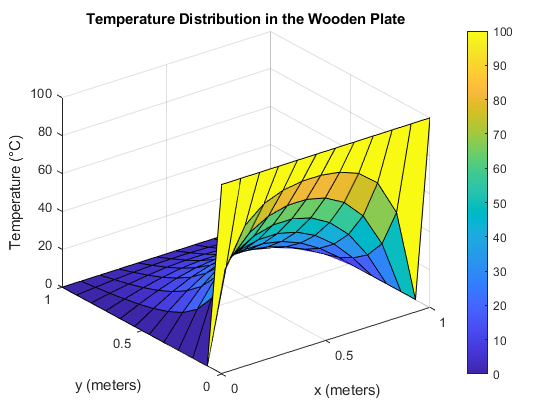


% Plotting the temperature distribution
[X, Y] = meshgrid(0:dx:L, 0:dx:L);
surf(X, Y, u);  % Surface plot
title('Temperature Distribution in the Wooden Plate');
xlabel('x (meters)');
ylabel('y (meters)');
zlabel('Temperature (°C)');
colorbar

Simulating Heat Transfer in Natural Biomaterials using Crank Nicholson Method

Problem:Simulate  heat transfer in a biomaterial(e.g a natural fibre mat  ) with : $\frac{\partial u}{\partial t}=\alpha\frac{\partial^2u}{\partial x^2}$

- Thermal diffusivity of wood,${\alpha=0.05m^2}{s}$

- Length(L) = 1 meter

- Initial  condition:$u\left(x,0\right)=\sin{\left(\pi x\right)}$            

- Boundary conditions: $u\left(0.t\right)=u\left(1,t\right)=0$           (fixed temperature at the ends)

- Time interval: $0\le t\le0.5\ $           seconds

- Number of spatial points:  N=10  

- Grid: N=20 spatial points, M = 100 time steps

Crank Nicolson Method is given by:$-\frac{\alpha k}{2h^2}u_{i-1}^{n+1}+\left(1+\frac{\alpha k}{h^2}\right)u_i^{n+1}-\frac{\alpha k}{2h^2}u_{i+1}^{n+1}=\frac{\alpha k}{2h^2}u_{i-1}^n+\left(1-\frac{\alpha k}{h^2}\right)u_i^n+\frac{\alpha k}{2h^2}u_{i+1}^n$

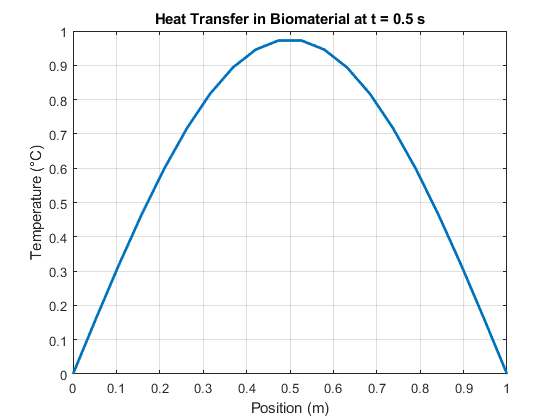

% Parameters
L = 1;                      % Length in meters
alpha = 0.005;              % Thermal diffusivity in m^2/s
T = 0.5;                    % Total time in seconds
N = 20;                     % Number of spatial points
M = 100;                    % Number of time steps

% Discretization
h = L / (N - 1);            % Spatial step size
k = T / M;                  % Time step size

% Initial and boundary conditions
x = linspace(0, L, N);     % Spatial grid
u = sin(pi * x);           % Initial condition

% Coefficients for the matrix
r = alpha * k / (2 * h^2);
A = diag(1 + 2*r * ones(N-2, 1)) + diag(-r * ones(N-3, 1), 1) + diag(-r * ones(N-3, 1), -1);
B = diag(1 - 2*r * ones(N-2, 1)) + diag(r * ones(N-3, 1), 1) + diag(r * ones(N-3, 1), -1);

% Time-stepping loop
for n = 1:M
    % Set up the right-hand side of the equation
    b = B * u(2:N-1)';
    b(1) = b(1) + r * 0;    % Boundary condition at x=0
    b(end) = b(end) + r * 0; % Boundary condition at x=1
    
    % Solve the linear system
    u(2:N-1) = A \ b;        % Update the interior points
end

% Plot results
figure;
plot(x, u, 'LineWidth', 2);
title('Heat Transfer in Biomaterial at t = 0.5 s');
xlabel('Position (m)');
ylabel('Temperature (°C)');
grid on;

## Systems of Linear Equations

**Direct Linear Methods**

**Structural Analysis of Mass Timber Beams**

Consider a glulam beam subjected to forces at different points. We need to calculate the forces acting on the beam at various points using a system of linear equations.

We have a system of equations representing the forces at different points on the beam that can be modeled as: $\left\lbrack \begin{array}{ccc}
3 & 2 & -1\\
2 & 3 & 1\\
1 & -1 & 3
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
\textrm{F1}\\
\textrm{F2}\\
\textrm{F3}
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
5\\
10\\
8
\end{array}\right\rbrack$

**Gaussian Elimination**

clear
% Define the system of linear equations
A = [3, 2, -1;
    2, 3, 1;
    1, -1, 2];
B = [5;
    10;
    8];

% Perform Gaussian Elimination
n = length(B); % Number of equations
AugmentedMatrix = [A B]; % Augmented matrix [A|B]

for i = 1:n
    % Partial pivoting (to prevent division by zero or small numbers)
    [~, maxIdx] = max(abs(AugmentedMatrix(i:n, i)));
    maxIdx = maxIdx + i - 1;
    AugmentedMatrix([i, maxIdx], :) = AugmentedMatrix([maxIdx, i], :);
    
    % Forward elimination
    for j = i+1:n
        factor = AugmentedMatrix(j, i) / AugmentedMatrix(i, i);
        AugmentedMatrix(j, i:n+1) = AugmentedMatrix(j, i:n+1) - factor * AugmentedMatrix(i, i:n+1);
    end
end

% Back substitution
X = zeros(n, 1);
X(n) = AugmentedMatrix(n, n+1) / AugmentedMatrix(n, n);
for i = n-1:-1:1
    X(i) = (AugmentedMatrix(i, n+1) - AugmentedMatrix(i, i+1:n) * X(i+1:n)) / AugmentedMatrix(i, i);
end

% Display the solution
disp('Solution using Gaussian Elimination:');

Solution using Gaussian Elimination:


disp(X);

    2.2500
    0.7500
    3.2500


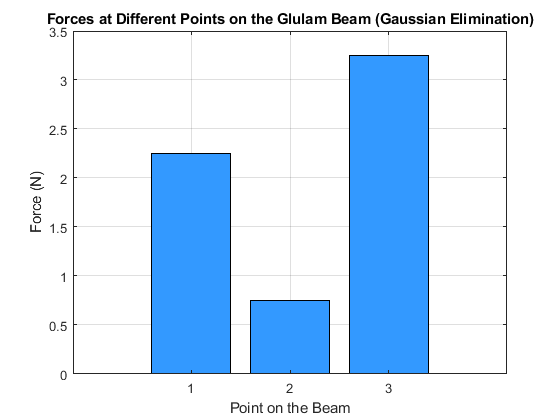


% Visualizing the result
figure;
bar([1, 2, 3], X, 'FaceColor', [0.2, 0.6, 1]);
xlabel('Point on the Beam');
ylabel('Force (N)');
title('Forces at Different Points on the Glulam Beam (Gaussian Elimination)');
grid on;

**Cramer's Rule**:

% Using Cramer's Rule
detA = det(A); % Determinant of A

% Calculate the determinants for each variable
A1 = A;
A1(:,1) = B; % Replace the first column of A with B
detA1 = det(A1);

A2 = A;
A2(:,2) = B; % Replace the second column of A with B
detA2 = det(A2);

A3 = A;
A3(:,3) = B; % Replace the third column of A with B
detA3 = det(A3);

% Solution using Cramer's Rule
F1 = detA1 / detA;
F2 = detA2 / detA;
F3 = detA3 / detA;

% Display the solution
disp('Solution using Cramer''s Rule:');

Solution using Cramer's Rule:


disp([F1, F2, F3]);

    2.2500    0.7500    3.2500


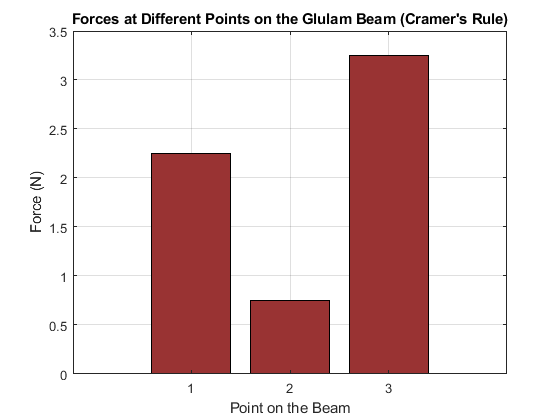


% Visualizing the result
figure;
bar([1, 2, 3], [F1, F2, F3], 'FaceColor', [0.6, 0.2, 0.2]);
xlabel('Point on the Beam');
ylabel('Force (N)');
title('Forces at Different Points on the Glulam Beam (Cramer''s Rule)');
grid on;

**LU Decomposition**

% LU Decomposition
[L, U, P] = lu(A); % LU Decomposition with permutation matrix

% Forward substitution to solve L * y = B
y = L \ (P * B);

% Back substitution to solve U * X = y
X_LU = U \ y;

% Display the solution
disp('Solution using LU Decomposition:');

Solution using LU Decomposition:


disp(X_LU);

    2.2500
    0.7500
    3.2500


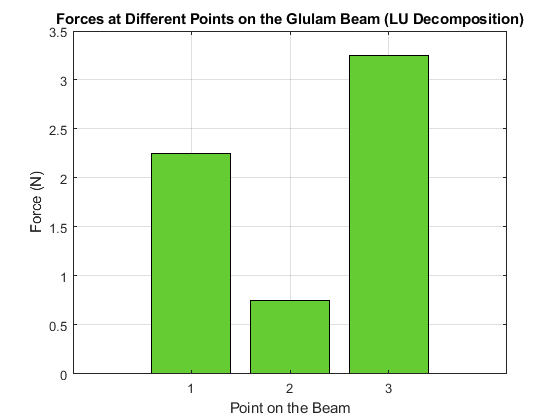


% Visualizing the result
figure;
bar([1, 2, 3], X_LU, 'FaceColor', [0.4, 0.8, 0.2]);
xlabel('Point on the Beam');
ylabel('Force (N)');
title('Forces at Different Points on the Glulam Beam (LU Decomposition)');
grid on;

**Iterative Linear Methods**

Analyze the deformation of a wooden beam subjected to several forces, using **iterative methods** to solve the system of linear equations arising from the equilibrium conditions.

We have a **system of linear equations** describing the deformation at different points on the beam. The system can be represented as:

A⋅X=B

Where:

- A is the coefficient matrix,

- X is the unknown displacement vector (the deformation at each point),

- B is the load vector applied at each point.

For a wooden beam with the following conditions:

- The beam is subjected to forces at different points (representing applied loads).

- The system of equations is derived from the beam’s equilibrium conditions.

A=$\left\lbrack \begin{array}{cccc}
4 & -1 & 0 & 0\\
-1 & 4 & -1 & 0\\
0 & -1 & 4 & -1\\
0 & 0 & -1 & 3
\end{array}\right\rbrack$, B=$\left\lbrack \begin{array}{c}
15\\
10\\
10\\
5
\end{array}\right\rbrack$

Here, A represents the stiffness of the beam and B represents the applied forces.

**Jacobi Method**

% Given data
A = [4 -1 0 0; -1 4 -1 0; 0 -1 4 -1; 0 0 -1 3];  % Coefficient matrix
B = [15; 10; 10; 5];  % Applied forces (load vector)
n = length(B);  % Number of unknowns (size of the system)
X = zeros(n,1);  % Initial guess (displacement vector)
X_new = X;  % Vector for the new iteration
iterations = 25;  % Number of iterations

% Jacobi Iteration
for k = 1:iterations
    for i = 1:n
        X_new(i) = (B(i) - A(i, [1:i-1, i+1:n]) * X([1:i-1, i+1:n])) / A(i,i);
    end
    X = X_new;
end

disp('Jacobi Method Displacement Vector:');

Jacobi Method Displacement Vector:


disp(X);

    4.9673
    4.8693
    4.5098
    3.1699


**Gauss-Seidel Method**

% Gauss-Seidel Iteration
X = zeros(n,1);  % Initial guess
iterations = 25;  % Number of iterations

for k = 1:iterations
    for i = 1:n
        X(i) = (B(i) - A(i, [1:i-1, i+1:n]) * X([1:i-1, i+1:n])) / A(i,i);
    end
end

disp('Gauss-Seidel Method Displacement Vector:');

Gauss-Seidel Method Displacement Vector:


disp(X);

    4.9673
    4.8693
    4.5098
    3.1699


**Successive Over-Relaxation (SOR) Method**

% SOR Iteration
omega = 1.25;  % Relaxation factor
X = zeros(n,1);  % Initial guess
iterations = 25;  % Number of iterations

for k = 1:iterations
    for i = 1:n
        X(i) = (1 - omega) * X(i) + omega * (B(i) - A(i, [1:i-1, i+1:n]) * X([1:i-1, i+1:n])) / A(i,i);
    end
end

disp('SOR Method Displacement Vector:');

SOR Method Displacement Vector:


disp(X);

    4.9673
    4.8693
    4.5098
    3.1699


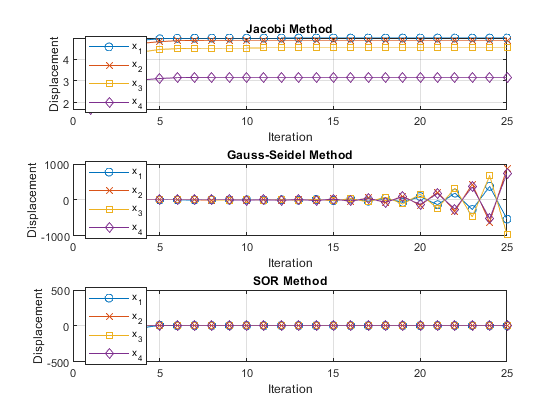

% Given data
A = [4 -1 0 0; -1 4 -1 0; 0 -1 4 -1; 0 0 -1 3];  % Coefficient matrix
B = [15; 10; 10; 5];  % Applied forces (load vector)
n = length(B);  % Number of unknowns (size of the system)

% Initial guess for displacement (initial guess vector)
X = zeros(n,1);  

% Set the number of iterations
iterations = 25;

% Create matrices to store displacement over iterations for each method
displacement_jacobi = zeros(n, iterations);   % For Jacobi
displacement_gauss_seidel = zeros(n, iterations);  % For Gauss-Seidel
displacement_sor = zeros(n, iterations);   % For SOR

% Relaxation parameter for SOR
omega = 1.25;

% Jacobi Method
X_jacobi = X;
for k = 1:iterations
    for i = 1:n
        % Jacobi update rule
        X_jacobi(i) = (B(i) - A(i, [1:i-1, i+1:n]) * X([1:i-1, i+1:n])) / A(i,i);
    end
    X = X_jacobi;
    displacement_jacobi(:, k) = X;  % Store the displacement for Jacobi
end

% Gauss-Seidel Method
X_gs = X;
for k = 1:iterations
    for i = 1:n
        % Gauss-Seidel update rule
        X_gs(i) = (B(i) - A(i, [1:i-1, i]) * X([1:i-1, i]) - A(i, [i+1:n]) * X([i+1:n])) / A(i,i);
    end
    X = X_gs;
    displacement_gauss_seidel(:, k) = X;  % Store the displacement for Gauss-Seidel
end

% Successive Over Relaxation (SOR) Method
X_sor = X;
for k = 1:iterations
    for i = 1:n
        % SOR update rule
        X_sor(i) = (1 - omega) * X_sor(i) + omega * (B(i) - A(i, [1:i-1, i+1:n]) * X_sor([1:i-1, i+1:n])) / A(i,i);
    end
    X = X_sor;
    displacement_sor(:, k) = X;  % Store the displacement for SOR
end

% Plotting the results
iterations_range = 1:iterations;

% Create subplots for each method
figure;

% Jacobi Method Plot
subplot(3, 1, 1);
plot(iterations_range, displacement_jacobi(1, :), '-o', 'DisplayName', 'x_1');
hold on;
plot(iterations_range, displacement_jacobi(2, :), '-x', 'DisplayName', 'x_2');
plot(iterations_range, displacement_jacobi(3, :), '-s', 'DisplayName', 'x_3');
plot(iterations_range, displacement_jacobi(4, :), '-d', 'DisplayName', 'x_4');
title('Jacobi Method');
xlabel('Iteration');
ylabel('Displacement');
legend('Location', 'best');
grid on;

% Gauss-Seidel Method Plot
subplot(3, 1, 2);
plot(iterations_range, displacement_gauss_seidel(1, :), '-o', 'DisplayName', 'x_1');
hold on;
plot(iterations_range, displacement_gauss_seidel(2, :), '-x', 'DisplayName', 'x_2');
plot(iterations_range, displacement_gauss_seidel(3, :), '-s', 'DisplayName', 'x_3');
plot(iterations_range, displacement_gauss_seidel(4, :), '-d', 'DisplayName', 'x_4');
title('Gauss-Seidel Method');
xlabel('Iteration');
ylabel('Displacement');
legend('Location', 'best');
grid on;

% SOR Method Plot
subplot(3, 1, 3);
plot(iterations_range, displacement_sor(1, :), '-o', 'DisplayName', 'x_1');
hold on;
plot(iterations_range, displacement_sor(2, :), '-x', 'DisplayName', 'x_2');
plot(iterations_range, displacement_sor(3, :), '-s', 'DisplayName', 'x_3');
plot(iterations_range, displacement_sor(4, :), '-d', 'DisplayName', 'x_4');
title('SOR Method');
xlabel('Iteration');
ylabel('Displacement');
legend('Location', 'best');
grid on;